# **Orbital Mechanics Project: Free-Return Trajectory for Earth-Moon Mission**

Code Initiation:

clc
clear
close all

set(0,'DefaultFigureWindowStyle','normal')

## Optimal Parking Orbit Altitude

For Hohmann Transfer between two circular orbits (from earth to parking orbit)

syms dVt dVp dVa ra z e
re = 6368;  % km
mu = 3.986e5;
ra = re + z

$$ra = z+6368$$

e = (ra - re)/(ra + re)

$$e = \frac{z}{z+12736}$$

dVp = sqrt(mu/re)*(sqrt(1 + e) - 1);

$$dVp = \frac{5\,\sqrt{199}\,\sqrt{1993}\,\left(\sqrt{\frac{z}{z+12736}+1}-1\right)}{398}$$

dVa = sqrt(mu/ra)*(1 - sqrt(1 - e));

$$dVa = -10\,\sqrt{3986}\,\left(\sqrt{1-\frac{z}{z+12736}}-1\right)\,\sqrt{\frac{1}{z+6368}}$$

f1 = dVt == abs(dVp) + abs(dVa);

$$f1 = \mathrm{dVt}=10\,\sqrt{3986}\,\left|\sqrt{1-\frac{z}{z+12736}}-1\right|\,\sqrt{\frac{1}{\left|z+6368\right|}}+\frac{5\,\sqrt{199}\,\sqrt{1993}\,\left|\sqrt{\frac{z}{z+12736}+1}-1\right|}{398}$$

dVt = rhs(f1);

$$dVt = 10\,\sqrt{3986}\,\left|\sqrt{1-\frac{z}{z+12736}}-1\right|\,\sqrt{\frac{1}{\left|z+6368\right|}}+\frac{5\,\sqrt{199}\,\sqrt{1993}\,\left|\sqrt{\frac{z}{z+12736}+1}-1\right|}{398}$$

derdVt = diff(dVt, z)

$$derdVt = \begin{array}{l} \frac{5\,\sqrt{3986}\,\left(\frac{\sigma_{4}\,\left(\bar{\sigma_{2}}-1\right)}{2\,\sigma_{2}}-\frac{\left(\sigma_{2}-1\right)\,\sigma_{1}}{2\,\bar{\sigma_{2}}}\right)\,\sigma_{5}}{\sqrt{\left(\sigma_{2}-1\right)\,\left(\bar{\sigma_{2}}-1\right)}}-\frac{5\,\sqrt{199}\,\sqrt{1993}\,\left(\frac{\sigma_{4}\,\left(\bar{\sigma_{3}}-1\right)}{2\,\sigma_{3}}-\frac{\left(\sigma_{3}-1\right)\,\sigma_{1}}{2\,\bar{\sigma_{3}}}\right)}{796\,\sqrt{\left(\sigma_{3}-1\right)\,\left(\bar{\sigma_{3}}-1\right)}}-\frac{5\,\sqrt{3986}\,\left|\sigma_{2}-1\right|\,\left(z+\bar{z}+12736\right)}{2\,{\left|z+6368\right|}^{2}\,\sqrt{\left(\bar{z}+6368\right)\,\left(z+6368\right)}\,\sigma_{5}}\\ \mathrm{where}\\ \sigma_{1}=\frac{1}{\bar{z}+12736}-\frac{\bar{z}}{{\left(\bar{z}+12736\right)}^{2}}\\ \sigma_{2}=\sqrt{1-\frac{z}{z+12736}}\\ \sigma_{3}=\sqrt{\frac{z}{z+12736}+1}\\ \sigma_{4}=\frac{z}{{\left(z+12736\right)}^{2}}-\frac{1}{z+12736}\\ \sigma_{5}=\sqrt{\frac{1}{\left|z+6368\right|}} \end{array}$$

f2 = 0 == derdVt;

$$f2 = \begin{array}{l} 0=\frac{5\,\sqrt{3986}\,\left(\frac{\sigma_{4}\,\left(\bar{\sigma_{2}}-1\right)}{2\,\sigma_{2}}-\frac{\left(\sigma_{2}-1\right)\,\sigma_{1}}{2\,\bar{\sigma_{2}}}\right)\,\sigma_{5}}{\sqrt{\left(\sigma_{2}-1\right)\,\left(\bar{\sigma_{2}}-1\right)}}-\frac{5\,\sqrt{199}\,\sqrt{1993}\,\left(\frac{\sigma_{4}\,\left(\bar{\sigma_{3}}-1\right)}{2\,\sigma_{3}}-\frac{\left(\sigma_{3}-1\right)\,\sigma_{1}}{2\,\bar{\sigma_{3}}}\right)}{796\,\sqrt{\left(\sigma_{3}-1\right)\,\left(\bar{\sigma_{3}}-1\right)}}-\frac{5\,\sqrt{3986}\,\left|\sigma_{2}-1\right|\,\left(z+\bar{z}+12736\right)}{2\,{\left|z+6368\right|}^{2}\,\sqrt{\left(\bar{z}+6368\right)\,\left(z+6368\right)}\,\sigma_{5}}\\ \mathrm{where}\\ \sigma_{1}=\frac{1}{\bar{z}+12736}-\frac{\bar{z}}{{\left(\bar{z}+12736\right)}^{2}}\\ \sigma_{2}=\sqrt{1-\frac{z}{z+12736}}\\ \sigma_{3}=\sqrt{\frac{z}{z+12736}+1}\\ \sigma_{4}=\frac{z}{{\left(z+12736\right)}^{2}}-\frac{1}{z+12736}\\ \sigma_{5}=\sqrt{\frac{1}{\left|z+6368\right|}} \end{array}$$

x = lhs(f2);

$$x = 0$$

% y = subs(rhs(f2), mu, 3.986e5)
y = rhs(f2);

$$y = \begin{array}{l} \frac{5\,\sqrt{3986}\,\left(\frac{\sigma_{4}\,\left(\bar{\sigma_{2}}-1\right)}{2\,\sigma_{2}}-\frac{\left(\sigma_{2}-1\right)\,\sigma_{1}}{2\,\bar{\sigma_{2}}}\right)\,\sigma_{5}}{\sqrt{\left(\sigma_{2}-1\right)\,\left(\bar{\sigma_{2}}-1\right)}}-\frac{5\,\sqrt{199}\,\sqrt{1993}\,\left(\frac{\sigma_{4}\,\left(\bar{\sigma_{3}}-1\right)}{2\,\sigma_{3}}-\frac{\left(\sigma_{3}-1\right)\,\sigma_{1}}{2\,\bar{\sigma_{3}}}\right)}{796\,\sqrt{\left(\sigma_{3}-1\right)\,\left(\bar{\sigma_{3}}-1\right)}}-\frac{5\,\sqrt{3986}\,\left|\sigma_{2}-1\right|\,\left(z+\bar{z}+12736\right)}{2\,{\left|z+6368\right|}^{2}\,\sqrt{\left(\bar{z}+6368\right)\,\left(z+6368\right)}\,\sigma_{5}}\\ \mathrm{where}\\ \sigma_{1}=\frac{1}{\bar{z}+12736}-\frac{\bar{z}}{{\left(\bar{z}+12736\right)}^{2}}\\ \sigma_{2}=\sqrt{1-\frac{z}{z+12736}}\\ \sigma_{3}=\sqrt{\frac{z}{z+12736}+1}\\ \sigma_{4}=\frac{z}{{\left(z+12736\right)}^{2}}-\frac{1}{z+12736}\\ \sigma_{5}=\sqrt{\frac{1}{\left|z+6368\right|}} \end{array}$$

zs = 100:50:5000;

zs =          100         150         200         250         300         350         400         450         500         550         600         650         700         750         800         850         900         950        1000        1050        1100        1150        1200        1250        1300        1350        1400        1450        1500        1550        1600        1650        1700        1750        1800        1850        1900        1950        2000        2050        2100        2150        2200        2250        2300        2350        2400        2450        2500        2550


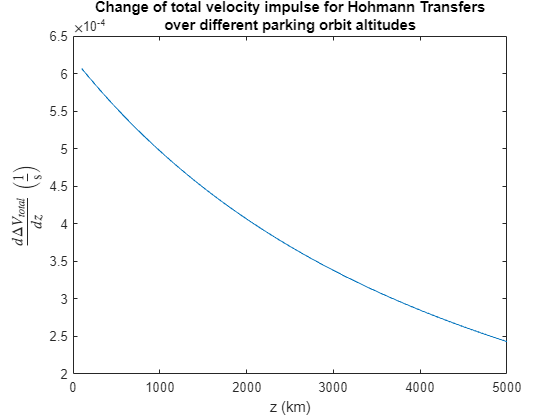

plot(zs, subs(y, z, zs))
title({'Change of total velocity impulse for Hohmann Transfers', 'over different parking orbit altitudes'})
xlabel('z (km)')
ylabel('$\frac{d\Delta V_{total}}{dz} \ \left(\frac{1}{\rm{s}}\right)$', Interpreter='latex')

% dVt = subs(dVt, mu, 3.986e5)
plot(zs, subs(dVt, z, zs))
% title({'Total Velocity Impulse required to perform Hohmann Transfer', 'for different parking orbit altitudes'})
xlabel('z')
ylabel('dVt')
hold on
syms dep 
dep = (mu/2)*( (1/re) - (1/ra) )

$$dep = \frac{49825}{1592}-\frac{199300}{z+6368}$$

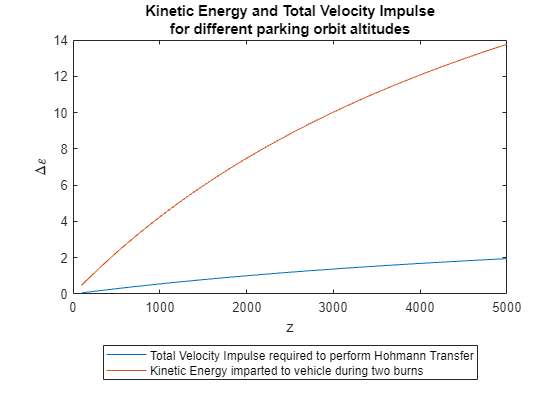

% dep = subs(dep, mu, 3.986e5)
plot(zs, subs(dep, z, zs))
title({'Kinetic Energy and Total Velocity Impulse', 'for different parking orbit altitudes'})
xlabel('z')
ylabel('$\Delta \varepsilon$', Interpreter='latex')
legend('Total Velocity Impulse required to perform Hohmann Transfer', 'Kinetic Energy imparted to vehicle during two burns', Location='southoutside')

Based on online sources, it is generally accepted that the optimal earth parking orbit is in LEO (Low Earth Orbit), which is between 160km - 2000km. Apollo 11 went into a nearly circular earth parking orbit of ~185.9 km. Since that mission was successful, a parking orbit of 190km will be used. It requires less total velocity impulse to obtain the orbit via Hohmann Transfer compared to higher LEOs, while still being high enough to avoid atmospheric drag.

So, for z = 190km, we can get $\Delta V_p$, $\Delta V_a$, and $\Delta V_{total}$

z_val = 190;    % km
dVp_val = double(subs(dVp, z, z_val));  dVa_val = double(subs(dVa, z, z_val));  dVt_val = dVp_val + dVa_val;
disp([dVp_val, dVa_val, dVt_val])

    0.0579    0.0575    0.1154



Assuming that the earth rotate counterclockwise, and 1 Sidereal Day = 86400 seconds, we can find the angular velocity of earth and thus the tangential velocity

siday = 86400;  % seconds
we = (2*pi) * re;
Ve = we / siday

Ve = 0.4631

Since c $\Delta V_p \approx \Delta V_a$, then at z = 190km, the velocity of our spacecraft is $V_e$. Since we needs a 3-hour system checkout in the parking orbit, we need to make sure that the orbit period is greater than 3 hours

sys_check = 3 * 60 * 60    % seconds

sys_check = 10800

a_po = re + z_val

a_po = 6558

T_po = 2*pi*sqrt((a_po^3)/mu)  % seconds

T_po = 5.2853e+03

if (T_po > sys_check)
    disp('Proceed')
else
    disp('Spacecraft will orbit Earth more than once')
end

Spacecraft will orbit Earth more than once


Find eccentricity of transfer ellipse toward Lunar radius

rp = a

rp = 6558

rm = 384400

rm = 384400

e_em = (rm - rp)/(rm + rp)

e_em = 0.9665

a_em = rp / (1 - e)

a_em = 1.9548e+05

a_em = rm / (1 + e)

a_em = 195479